# Function approximation

wiki: [https://en.wikipedia.org/wiki/Function_approximation](https://en.wikipedia.org/wiki/Function_approximation)

definition: **select a function among a well-defined class that closely matches ("approximates") a target function in a task-specific way**

## Taylor series

wiki: [https://en.wikipedia.org/wiki/Taylor_series](https://en.wikipedia.org/wiki/Taylor_series)

A special case of Pade approximation.

## Pade approximation

wiki: [https://en.wikipedia.org/wiki/Pad%C3%A9_approximant](https://en.wikipedia.org/wiki/Pad%C3%A9_approximant)

target function: $$$
f\left( x \right)$$
$

function collection: $$$
\frac{P_L\left( x \right)}{Q_M\left( x \right)}\approx f\left( x \right)
$$
$

- 
$$$$
P_L\left( x \right) =p_0+p_1x+...+p_Lx^L
$$
$$


- 
$$$$
Q_M\left( x \right) =1+q_1x+...+q_Mx^M
$$
$$


process

- Taylor expansion: $$$
f\left( x \right) \approx \sum_{n=0}^{n=L+M}{A_nx^n}
$$
$

- then: $$$
Q_M\left( x \right) \sum_{n=0}^{n=L+M}{A_nx^n}\approx P_L\left( x \right) 
$$
$


$$$$
\left\{ \begin{array}{rcc}
	p_0&=&A_0\\
	p_1-A_0q_1&=&A_1\\
	p_2-A_1q_1-A_0q_2&=&A_2\\
	&...&\\
	p_L-A_{L-1}q_1-...-A_0q_L&=&A_L\\
	-A_Lq_1-...-A_{L-M+1}q_M&=&A_{L+1}\\
	&...&\\
	-A_{L+M-1}q_1-...-A_Lq_M&=&A_{L+M}\\
\end{array} \right. 
$$
$$



$$$$
\left(\matrix{
	1&		&		&		&		&		0&		&		&		&		\cr
	&		1&		&		&		&		-A_0&		0&		&		&		\cr
	&		&		1&		&		&		-A_1&		-A_0&		0&		&		\cr
	&		&		&		\ddots&		&		\vdots&		\vdots&		\vdots&		\ddots&		\vdots\cr
	&		&		&		&		1&		-A_{L-1}&		-A_{L-2}&		-A_{L-3}&		\ddots&		\vdots\cr
	&		&		&		&		&		\vdots&		\vdots&		\vdots&		\ddots&		\vdots\cr
	&		&		&		&		&		-A_{L+M-1}&		-A_{L+M-2}&		-A_{L+M-3}&		\cdots&		-A_L\cr
}\right) \left( \begin{array}{c}
	p_0\\
	p_1\\
	p_2\\
	\vdots\\
	p_L\\
	q_1\\
	q_2\\
	q_3\\
	\vdots\\
	q_M\\
\end{array} \right) =\left( \begin{array}{c}
	A_0\\
	A_1\\
	A_2\\
	\vdots\\
	A_L\\
	\vdots\\
	A_{L+M}\\
\end{array} \right) 
$$
$$


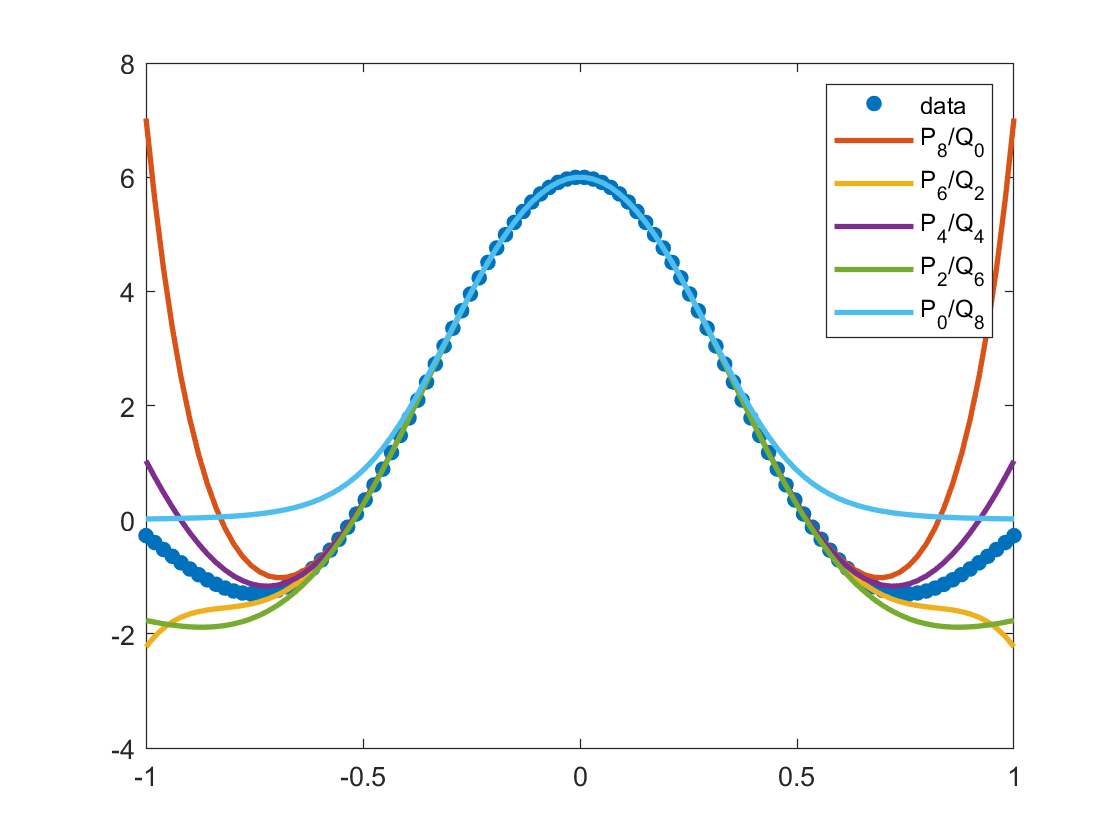

%symbolic toolbox needed, otherwise need to calculate high order taylor coeffcient by hand
syms x
expr1 = sin(6*x)/x;
taylor_coefficient = sym2poly(taylor(expr1,x,'order',9));

data_x = linspace(-1,1,100);
data_y = double(subs(expr1,x,data_x));

fig = figure();
ax = axes('Parent', fig, 'NextPlot', 'add', 'Box', 'on');

hline0 = plot(data_x, data_y, '.', 'MarkerSize',20);

[p,q] =  my_pade_approximation(taylor_coefficient, 8);
y = polyval(p,data_x)./polyval(q,data_x);
hline1 = plot(data_x, y,'LineWidth',2);

[p,q] =  my_pade_approximation(taylor_coefficient, 6);
y = polyval(p,data_x)./polyval(q,data_x);
hline2 = plot(data_x, y,'LineWidth',2);

[p,q] =  my_pade_approximation(taylor_coefficient, 4);
y = polyval(p,data_x)./polyval(q,data_x);
hline3 = plot(data_x, y,'LineWidth',2);

[p,q] =  my_pade_approximation(taylor_coefficient, 2);
y = polyval(p,data_x)./polyval(q,data_x);
hline4 = plot(data_x, y,'LineWidth',2);

[p,q] =  my_pade_approximation(taylor_coefficient, 0);
y = polyval(p,data_x)./polyval(q,data_x);
hline5 = plot(data_x, y,'LineWidth',2);

legend([hline0,hline1,hline2,hline3,hline4,hline5],{'data','P_8/Q_0','P_6/Q_2','P_4/Q_4','P_2/Q_6','P_0/Q_8'})

## function

function [p,q] = my_pade_approximation(taylor_coefficient, L)
% Pade approximation
% taylor_coeffient(int, (1,N1)): from high order to zero-order
% L(int, (1,1))
% p(float,(1,L+1)): from high order to zero-order
% q(float,(1,M+1)), from high order to zero-order, remember to add zero-order coefficient which is one
%
% reference:
%   wiki: https://en.wikipedia.org/wiki/Pad%C3%A9_approximant
%   http://mathworld.wolfram.com/PadeApproximant.html
%   http://mathfaculty.fullerton.edu/mathews/n2003/pade/PadeApproximationProof.pdf
M = size(taylor_coefficient,2) - 1 - L;
reverse_taylor = flip(taylor_coefficient, 2);
tmp1 = full(spdiags(repmat(reverse_taylor(1:(end-1)),M,1),-1:-1:(-L-M),L+M+1,M));
matA = [[eye(L+1); zeros(M,L+1)], -tmp1];
tmp1 = matA\reverse_taylor.';
p = flip(tmp1(1:L+1),1).';
q = [flip(tmp1(L+2:end),1).',1];
end
